# Configure and Simulate AUTOSAR Function Inhibition Service Calls

Simulate AUTOSAR component calls to Basic Software function inhibition and related services by using reference implementations. 

## Configure Calls to AUTOSAR Basic Software Services

The AUTOSAR standard defines Basic Software (BSW) services that run in the AUTOSAR run-time environment. The services include Diagnostic Event Manager (Dem), Function Inhibition Manager (FiM), and NVRAM Manager (NvM) services. In the AUTOSAR run-time environment, AUTOSAR software components typically access BSW services using client-server or sender-receiver communication.

In your AUTOSAR software component model, to implement client calls to FiM and related Dem service interfaces, you drag and drop preconfigured FiM and Dem caller blocks. Each block has prepopulated parameters, such as **Client port name **and **Operation**. You configure the block parameters, for example, to select a service operation to call. To configure the added caller blocks in the AUTOSAR software component, you synchronize the model. The software creates AUTOSAR client-service interfaces, operations, and ports, and maps each Simulink function call to an AUTOSAR client port and operation. For more information, see [Configure Calls to AUTOSAR Function Inhibition Manager Service](docid:autosar_ug.mw_a0e9dace-a451-4695-912b-de28eff43dd6).

Here is a function inhibition integration model, which integrates two sensor components, a monitor component, and an operation cycle component. The sensor components call BSW FiM and Dem (and NvM) services, the monitor component calls BSW FiM and Dem services, and the operation cycle component calls a BSW Dem service.

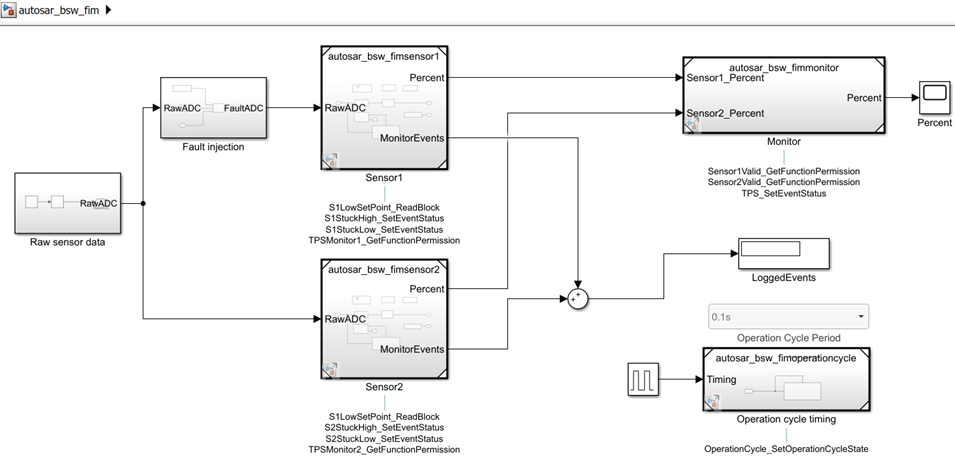

The sensor and monitor components each call the FiM service interface `FunctionInhibition`. The calls are implemented using the BSW library block Function Inhibition Caller. Each block instance is configured to call the `FunctionInhibition` operation `GetFunctionPermission`.

The operation cycle component calls the Dem service interface `OperationCycle`. The call is implemented using the BSW library block DiagnosticOperationCycleCaller. The block is configured to call the `OperationCycle` operation `SetOperationCycleState`.

## Configure Reference Implementations of AUTOSAR Basic Software Services for Simulation

To simulate an AUTOSAR component model that calls BSW services, create a containing composition, system, or harness model. In that containing model, provide reference implementations of the Dem, FiM, and NvM service operations called by the component.

The AUTOSAR Basic Software block library includes a Diagnostic Service Component block and an NVRAM Service Component block. The blocks provide reference implementations of Dem, FiM, and NvM service operations. To support simulation of component calls to the Dem, FiM, and NvM services, include the blocks in the containing model. You can insert the blocks in either of two ways:

- Automatically insert the blocks by creating a Simulink Test harness model

- Manually insert the blocks into a containing composition, system, or harness model, and then update the model

Here is the function inhibition integration model after manually inserting Diagnostic and NVRAM Service Component blocks. To display function connections, on the **Debug** tab, select **Information Overlays > Function Connectors**.

open_system('autosar_bsw_fim');

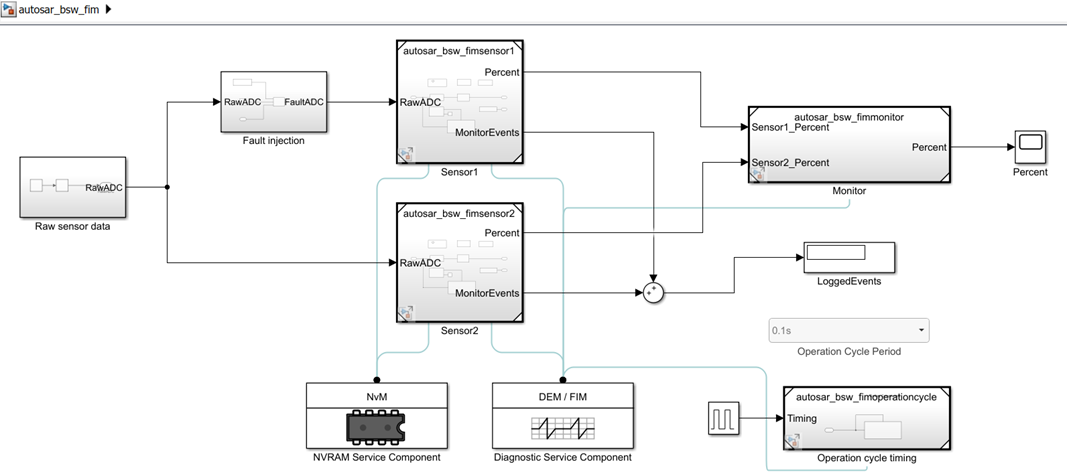

The Diagnostic Service Component block has prepopulated parameters, including RTE service ID parameters, Dem **Counter-Based Debouncing** parameters, and FiM inhibition condition parameters. The RTE tab lists component client ports and their mapping to Dem or FiM service IDs for events, operation cycles, or functions with inhibition conditions. Each row in the table represents a call into Dem or FiM services from a Basic Software caller block, for which you can modify an ID value.

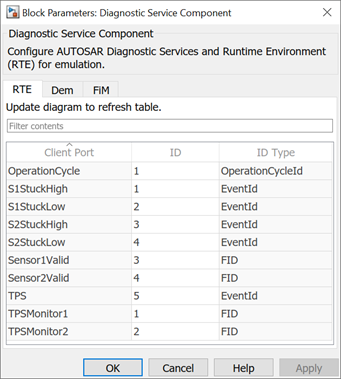

The FIM tab lists function identifiers (FIDs) and their associated inhibition conditions and client ports. The tab provides graphical controls for adding or removing inhibition conditions for a selected FID. For each inhibition condition, select ID and mask values.

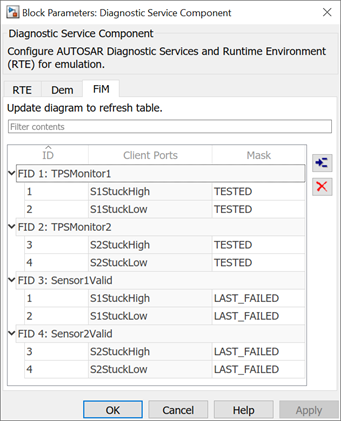

For more information, see [Configure Calls to AUTOSAR Function Inhibition Manager Service](docid:autosar_ug.mw_a0e9dace-a451-4695-912b-de28eff43dd6).

## Simulate Calls to AUTOSAR FiM and Dem Services

After configuring Diagnostic and NVRAM Service Component blocks in the integration model, simulate the model. The simulation exercises the AUTOSAR FiM and Dem service calls in the sensor, monitor, and operation cycle component models.

open_system('autosar_bsw_fim');
simOutIntegration = sim('autosar_bsw_fim');

## Related Links

- [Model AUTOSAR Basic Software Service Calls](docid:autosar_ug.bvh674b-1)

- [Configure Calls to AUTOSAR Function Inhibition Manager Service](docid:autosar_ug.mw_a0e9dace-a451-4695-912b-de28eff43dd6)

- [Configure AUTOSAR Basic Software Service Implementations for Simulation](docid:autosar_ug.mw_b97bc016-9a16-43c7-acf9-801b65b75f32)

*Copyright 2020 The MathWorks, Inc.*